# Neurodata Without Borders Extracellular Electrophysiology Tutorial

## This tutorial

Create fake data for a hypothetical extracellular electrophysiology experiment. The types of data we will convert are:

- Voltage recording

- Local field potential (LFP)

- Spike times

It is recommended to first work through the [Introduction to MatNWB tutorial](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/intro.html), which demonstrates installing MatNWB and creating an NWB file with subject information, animal position, and trials, as well as writing and reading NWB files in MATLAB.

## Setting up the NWB File

An NWB file represents a single session of an experiment. Each file must have a session_description, identifier, and session start time. Create a new [`NWBFile`](https://neurodatawithoutborders.github.io/matnwb/doc/NwbFile.html) object with those and additional metadata. For all MatNWB functions, we use the Matlab method of entering keyword argument pairs, where arguments are entered as name followed by value.

nwb = NwbFile( ...
    'session_description', 'mouse in open exploration',...
    'identifier', 'Mouse5_Day3', ...
    'session_start_time', datetime(2018, 4, 25, 2, 30, 3, 'TimeZone', 'local'), ...
    'timestamps_reference_time', datetime(2018, 4, 25, 3, 0, 45, 'TimeZone', 'local'), ...
    'general_experimenter', 'Last Name, First Name', ... % optional
    'general_session_id', 'session_1234', ... % optional
    'general_institution', 'University of My Institution', ... % optional
    'general_related_publications', {'DOI:10.1016/j.neuron.2016.12.011'}); % optional
nwb

nwb =   NwbFile with properties:

                                             nwb_version: '2.7.0'
                                        file_create_date: []
                                              identifier: 'Mouse5_Day3'
                                     session_description: 'mouse in open exploration'
                                      session_start_time: {[2018-04-25T02:30:03.000000+02:00]}
                               timestamps_reference_time: {[2018-04-25T03:00:45.000000+02:00]}
                                             acquisition: [0×1 types.untyped.Set]
                                                analysis: [0×1 types.untyped.Set]
                                                 general: [0×1 types.untyped.Set]
                                 general_data_collection: ''
                                         general_devices: [0×1 types.untyped.Set]
                          general_expe

## Extracellular Electrophysiology

In order to store extracellular electrophysiology data, you first must create an electrodes table describing the electrodes that generated this data. Extracellular electrodes are stored in an `electrodes` table, which is also a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html). `electrodes` has several required fields: `x`, `y`, `z`, `impedance`, `location`, `filtering`, and `electrode_group`.

## Electrodes Table

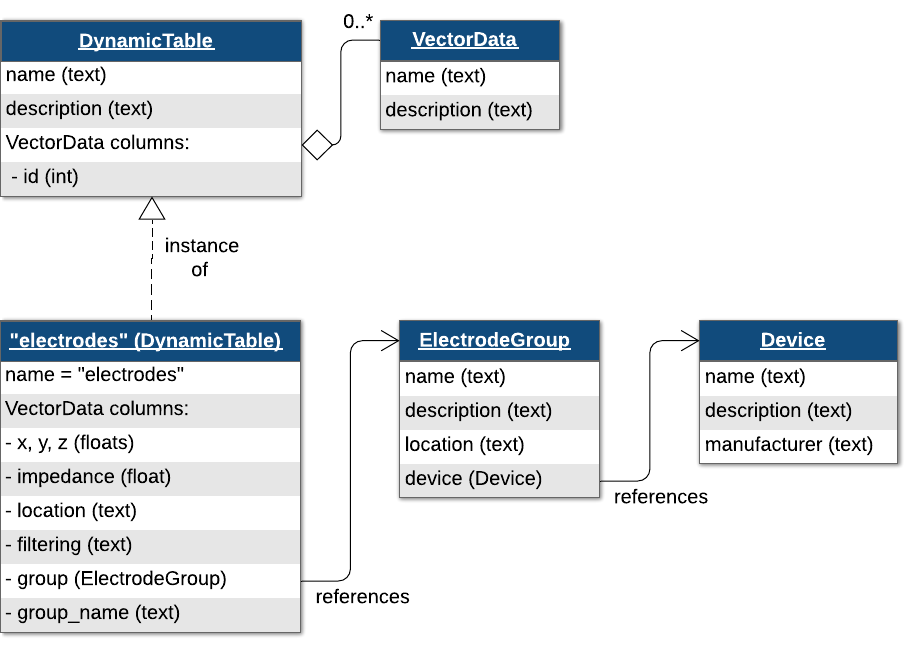

Since this is a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html), we can add additional metadata fields. We will be adding a "label" column to the table.

numShanks = 4;
numChannelsPerShank = 3;

ElectrodesDynamicTable = types.hdmf_common.DynamicTable(...
    'colnames', {'location', 'group', 'group_name', 'label'}, ...
    'description', 'all electrodes');

Device = types.core.Device(...
    'description', 'the best array', ...
    'manufacturer', 'Probe Company 9000' ...
);
nwb.general_devices.set('array', Device);
for iShank = 1:numShanks
    shankGroupName = sprintf('shank%d', iShank);
    EGroup = types.core.ElectrodeGroup( ...
        'description', sprintf('electrode group for %s', shankGroupName), ...
        'location', 'brain area', ...
        'device', types.untyped.SoftLink(Device) ...
    );
    
    nwb.general_extracellular_ephys.set(shankGroupName, EGroup);
    for iElectrode = 1:numChannelsPerShank
        ElectrodesDynamicTable.addRow( ...
            'location', 'unknown', ...
            'group', types.untyped.ObjectView(EGroup), ...
            'group_name', shankGroupName, ...
            'label', sprintf('%s-electrode%d', shankGroupName, iElectrode));
    end
end
ElectrodesDynamicTable.toTable() % Display the table

ans = 12×5 table
    id     location                 group                group_name            label        
    __    ___________    ____________________________    __________    _____________________

     0    {'unknown'}    1×1 types.untyped.ObjectView    {'shank1'}    {'shank1-electrode1'}
     1    {'unknown'}    1×1 types.untyped.ObjectView    {'shank1'}    {'shank1-electrode2'}
     2    {'unknown'}    1×1 types.untyped.ObjectView    {'shank1'}    {'shank1-electrode3'}
     3    {'unknown'}    1×1 types.untyped.ObjectView    {'shank2'}    {'shank2-electrode1'}
     4    {'unknown'}    1×1 types.untyped.ObjectView    {'shank2'}    {'shank2-electrode2'}
     5    {'unknown'}    1×1 types.untyped.ObjectView    {'shank2'}    {'shank2-electrode3'}
     6    {'unknown'}    1×1 types.untyped.ObjectView    {'shank3'} 


nwb.general_extracellular_ephys_electrodes = ElectrodesDynamicTable;

## Links

In the above loop, we create [`ElectrodeGroup`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectrodeGroup.html) objects. The `electrodes` table then uses an `ObjectView` in each row to link to the corresponding [`ElectrodeGroup`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectrodeGroup.html) object. An `ObjectView` is an object that allow you to create a link from one neurodata type referencing another. 

## ElectricalSeries

Voltage data are stored in [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects. [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) is a subclass of [`TimeSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/TimeSeries.html) specialized for voltage data. In order to create our [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) object, we will need to reference a set of rows in the `electrodes` table to indicate which electrodes were recorded. We will do this by creating a [`DynamicTableRegion`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTableRegion.html), which is a type of link that allows you to reference specific rows of a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html), such as the `electrodes` table, by row indices.

Create a [`DynamicTableRegion`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTableRegion.html) that references all rows of the `electrodes` table.

electrode_table_region = types.hdmf_common.DynamicTableRegion( ...
    'table', types.untyped.ObjectView(ElectrodesDynamicTable), ...
    'description', 'all electrodes', ...
    'data', (0:length(ElectrodesDynamicTable.id.data)-1)');

Now create an `ElectricalSeries` object to hold acquisition data collected during the experiment.

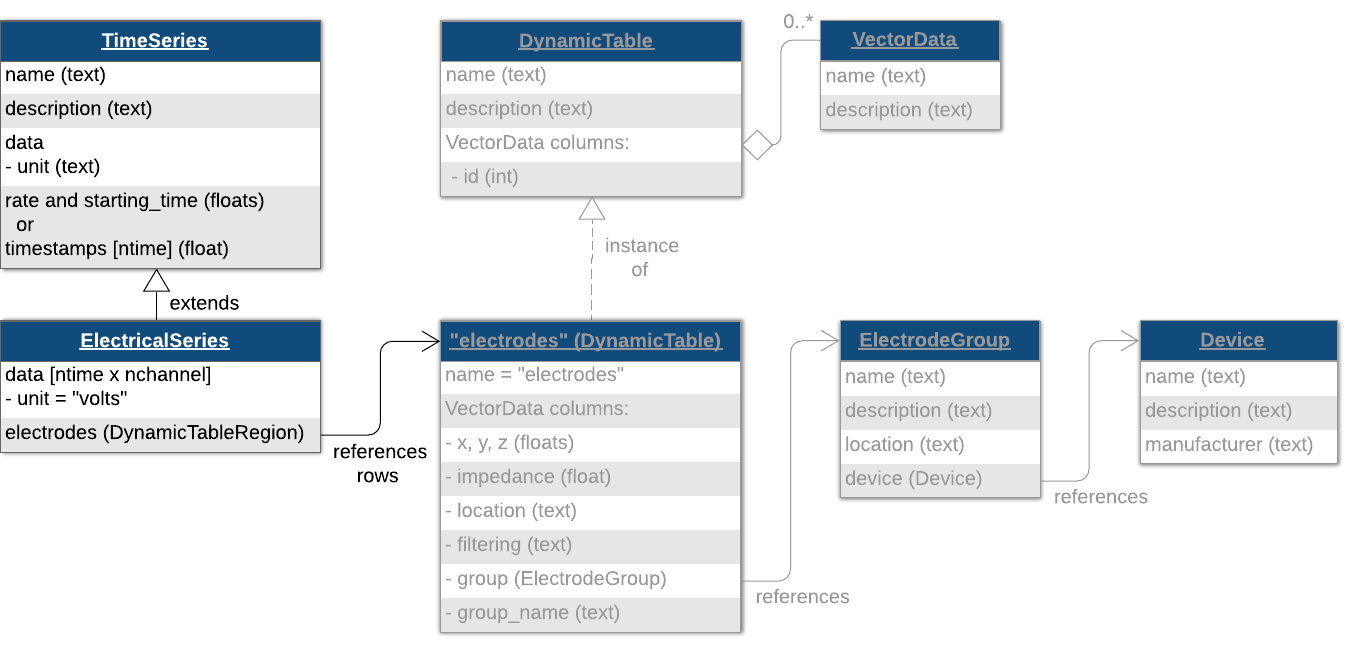

electrical_series = types.core.ElectricalSeries( ...
    'starting_time', 0.0, ... % seconds
    'starting_time_rate', 30000., ... % Hz
    'data', randn(12, 3000), ...
    'electrodes', electrode_table_region, ...
    'data_unit', 'volts');

This is the voltage data recorded directly from our electrodes, so it goes in the acquisition group. 

nwb.acquisition.set('ElectricalSeries', electrical_series);

## LFP

Local field potential (LFP) refers in this case to data that has been downsampled and/or filtered from the original acquisition data and is used to analyze signals in the lower frequency range. Filtered and downsampled LFP data would also be stored in an [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html). To help data analysis and visualization tools know that this [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) object represents LFP data, store it inside an `LFP` object, then place the `LFP` object in a [`ProcessingModule`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ProcessingModule.html) named `'ecephys'`. This is analogous to how we stored the [`SpatialSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/SpatialSeries.html) object inside of a [`Position`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Position.html) object and stored the [`Position`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Position.html) object in a [`ProcessingModule`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ProcessingModule.html) named `'behavior'` earlier.

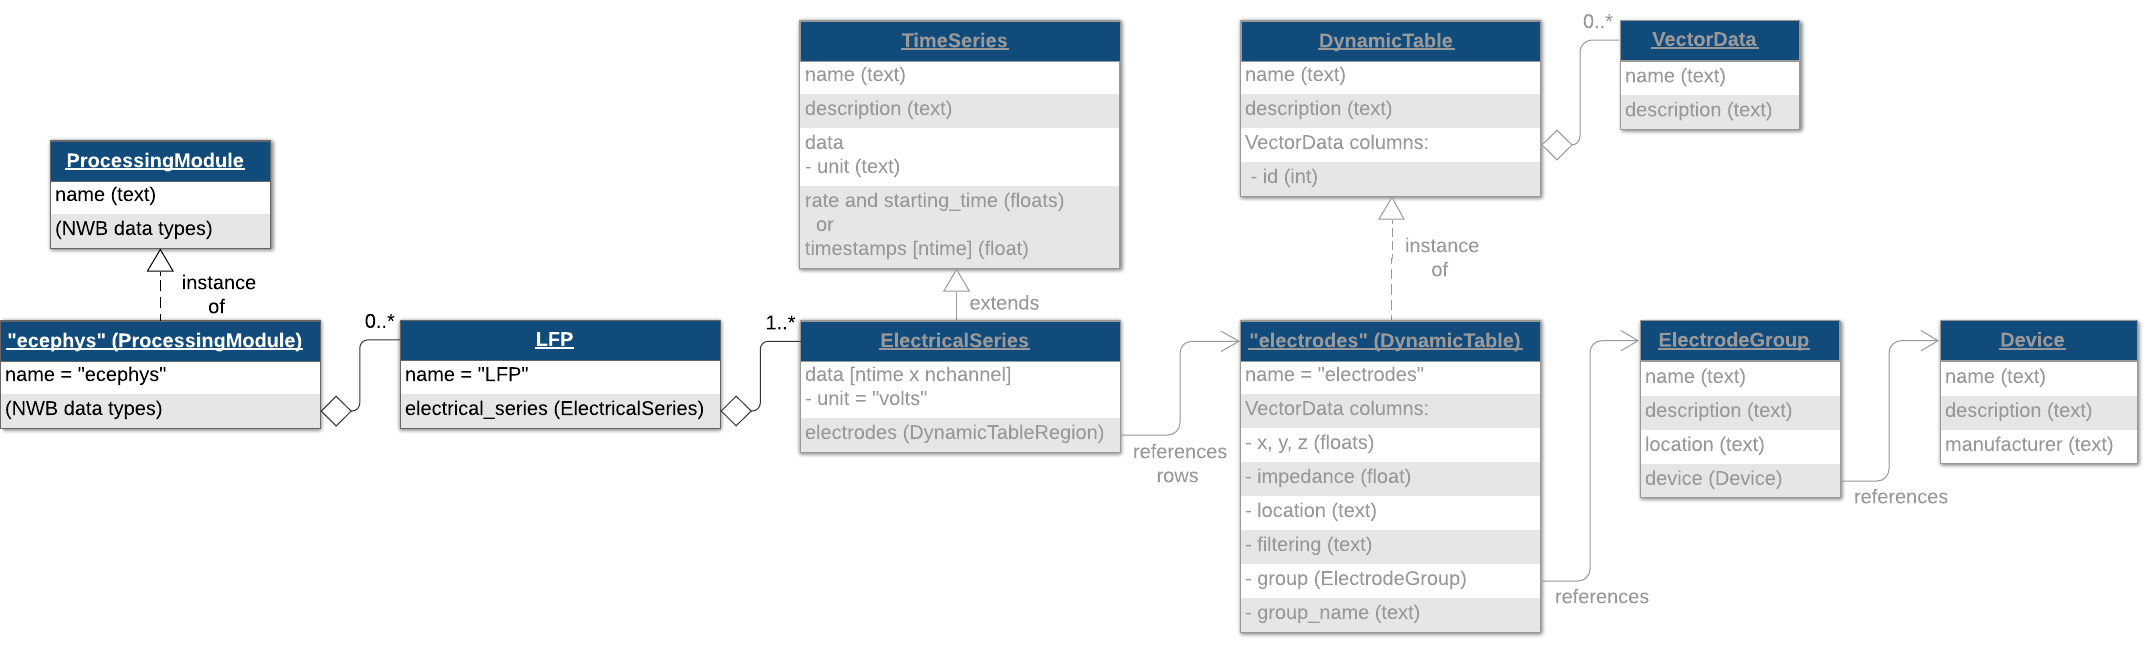

lfp_electrical_series = types.core.ElectricalSeries( ...
    'starting_time', 0.0, ... % seconds
    'starting_time_rate', 1000., ... % Hz
    'data', randn(12, 100), ...
    'electrodes', electrode_table_region, ...
    'data_unit', 'volts');

lfp = types.core.LFP('ElectricalSeries', lfp_electrical_series);

ecephys_module = types.core.ProcessingModule(...
    'description', 'extracellular electrophysiology');

ecephys_module.nwbdatainterface.set('LFP', lfp);
nwb.processing.set('ecephys', ecephys_module);

### Decomposition of LFP Data into Frequency Bands

In some cases, you may want to further process the LFP data and decompose the signal into different frequency bands for additional downstream analyses. You can store the processed data from these spectral analyses using a [`DecompositionSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/DecompositionSeries.html) object. This object allows you to include metadata about the frequency bands and metric used (e.g., `power`, `phase`, `amplitude`), as well as link the decomposed data to the original [`TimeSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/TimeSeries.html) signal the data was derived from.

**Note**: When adding data to a [`DecompositionSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/DecompositionSeries.html), the `data` argument is assumed to be 3D where the first dimension is time, the second dimension is channels, and the third dimension is bands. In MatNWB, the data needs to be permuted because the dimensions are written to file in reverse order (See the [dimensionMapNoDataPipes](matlab:open('./dimensionMapNoDataPipes.mlx')) tutorial)

% Define the frequency bands of interest (in Hz):
band_names = {'theta'; 'beta'; 'gamma'};
band_limits = [[4.0, 12.0]; [12.0, 30.0]; [30.0, 80.0]];

% The bands should be added to the DecompositionSeries as a dynamic table
bands = table(band_names, band_limits, 'VariableNames', {'band_names', 'band_limits'})

bands = 3×2 table
    band_names    band_limits
    __________    ___________

    {'theta'}       4    12  
    {'beta' }      12    30  
    {'gamma'}      30    80  


bands = util.table2nwb( bands );

% Generate random phase data for the demonstration.
phase_data = randn(50, 12, numel(band_names)); % 50 samples, 12 channels, 3 frequency bands
phase_data = permute(phase_data, [3,2,1]); % See dimensionMapNoDataPipes tutorial

decomp_series = types.core.DecompositionSeries(...
    'data', phase_data, ...
    'bands', bands, ...
    'metric', 'phase', ...
    'starting_time', 0.0, ... % seconds
    'starting_time_rate', 1000.0, ... % Hz
    'source_channels', electrode_table_region, ...
    'source_timeseries', lfp_electrical_series);

% Add decomposition series to ecephys module
ecephys_module.nwbdatainterface.set('theta', decomp_series);

## Sorted Spike Times

#### Ragged Arrays

Spike times are stored in another [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html) of subtype [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html). The default `Units` table is at `/units` in the HDF5 file. You can add columns to the [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table just like you did for `electrodes` and `trials`. Here, we generate some random spike data and populate the table. 

num_cells = 10;
firing_rate = 20;
spikes = cell(1, num_cells);
for iShank = 1:num_cells
    spikes{iShank} = rand(1, randi([16, 28]));
end
spikes

spikes = 1×10 cell array
    {[0.5058 0.2954 0.2989 0.9274 0.9732 0.9797 0.6497 0.1544 0.1931 0.9383 0.2508 0.2213 0.8137 0.4414 0.7633 0.1503 0.0919 0.1765 0.2095 0.5306 0.2564 0.9774 0.0412 0.7859]}    {[0.7393 0.4162 0.5171 0.4322 0.1792 0.5587 0.2921 0.2578 0.6008 0.6907 0.4773 0.1153 0.6401 0.4716 1.0000 0.3444 0.2300 0.0711 0.0300 0.1634 0.2222 0.3741 0.8904 0.1578 0.5728]}    {[0.3995 0.1438 0.8646 0.7312 0.7131 0.2525 0.9497 0.6856 0.2102 0.1928 0.6514 0.1288 0.1077 0.9046 0.2649 0.0770 0.3037 0.6670 0.6309 0.0801 0.3674 0.9211 0.8159 0.2589]}    {[0.6786 0.0050 0.4420 0.0949 0.5219 0.3932 0.9876 0.6576 0.5774 0.7630 0.7988 0.9090 0.3090 0.1669 0.8553 0.2779 0.1954 0.4156 0.1003 0.0102 0.0423]}    {[0.2605 0.5169 0.6096 0.1775 0.0686 0.9500 0.6797 0.7300 0.5685 0.4949 0.3865 0.0743 0.3660 0.7646 0.1844 0.5190 0.8153 0.4784 0.3529 0.7913 0.1014 0.8406 0.6236]}    {[0.0879 0.9903 0.0841 0.8023 0.1568 0.9599 0.8018 0.1208 0.8756 0.8673 0.4561 0.0432 0.1499 0.9902 0.4919 0.9305 0.0

Spike times are an example of a ragged array- it's like a matrix, but each row has a different number of elements. We can represent this type of data as an indexed column of the units [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html). These indexed columns have two components, the vector data object that holds the data and the vector index object that holds the indices in the vector that indicate the row breaks. You can use the convenience function `util.create_indexed_column` to create these objects.

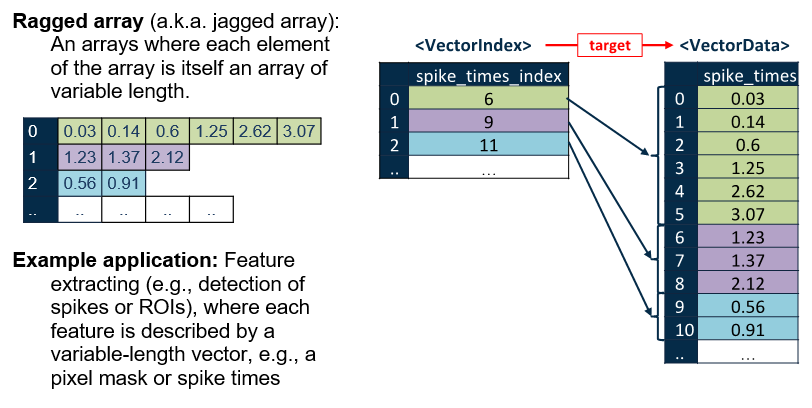

[spike_times_vector, spike_times_index] = util.create_indexed_column(spikes);

nwb.units = types.core.Units( ...
    'colnames', {'spike_times'}, ...
    'description', 'units table', ...
    'spike_times', spike_times_vector, ...
    'spike_times_index', spike_times_index ...
);

nwb.units.toTable

ans = 10×2 table
    id     spike_times 
    __    _____________

     1    {24×1 double}
     2    {25×1 double}
     3    {24×1 double}
     4    {21×1 double}
     5    {23×1 double}
     6    {20×1 double}
     7    {28×1 double}
     8    {25×1 double}
     9    {26×1 double}
    10    {23×1 double}


## Unsorted Spike Times

In MATLAB, while the [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table is used to store spike times and waveform data for spike-sorted, single-unit activity, you may also want to store spike times and waveform snippets of unsorted spiking activity. This is useful for recording multi-unit activity detected via threshold crossings during data acquisition. Such information can be stored using [`SpikeEventSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/SpikeEventSeries.html) objects.

% In the SpikeEventSeries the dimensions should be ordered as 
% [num_events, num_channels, num_samples].
% Define spike snippets: 20 events, 3 channels, 40 samples per event. 
spike_snippets = rand(20, 3, 40);
% Permute spike snippets (See dimensionMapNoDataPipes tutorial)
spike_snippets = permute(spike_snippets, [3,2,1]) 

spike_snippets = spike_snippets(:,:,1) =

    0.1429    0.9259    0.0700
    0.0400    0.7178    0.7009
    0.5971    0.3365    0.4316
    0.9264    0.9238    0.7397
    0.2612    0.7449    0.5528
    0.5117    0.0528    0.3843
    0.5694    0.3073    0.6741
    0.4110    0.9927    0.3482
    0.6506    0.1116    0.3662
    0.7461    0.5746    0.4627
    0.7129    0.2855    0.7947
    0.5606    0.1852    0.8944
    0.0834    0.1806    0.4122
    0.9656    0.8944    0.3009
    0.7063    0.3273    0.4278
    0.6046    0.9000    0.4736
    0.8320    0.5920    0.2394
    0.6989    0.8477    0.9060
    0.4957    0.0090    0.8987
    0.0527    0.0115    0.1328
    0.3439    0.7164    0.0280
    0.7949    0.2902    0.3710
    0.2989    0.0608    0.2231
    0.1163    0.0803    0.3157
    0.0866    0.7330    0.6571
    0.8264    0.2056    0.5102
    0.5544    0.5246    0.8982
    0.8769    0.9194    0.1817
    0.5827    0.3046    0.9821
    0.5704    0.9420    0.3976
    0.6810    0.7627    0.79


% Create electrode table region referencing electrodes 0, 1, and 2
shank0_table_region = types.hdmf_common.DynamicTableRegion( ...
    'table', types.untyped.ObjectView(ElectrodesDynamicTable), ...
    'description', 'shank0', ...
    'data', (0:2)');

% Define spike event series for unsorted spike times
spike_events = types.core.SpikeEventSeries( ...
    'data', spike_snippets, ...
    'timestamps', (0:19)', ...  % Timestamps for each event
    'description', 'events detected with 100uV threshold', ...
    'electrodes', shank0_table_region ...
);

% Add spike event series to NWB file acquisition
nwb.acquisition.set('SpikeEvents_Shank0', spike_events);

## Designating Electrophysiology Data

As mentioned above, [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects are meant for storing specific types of extracellular recordings. In addition to this [`TimeSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/TimeSeries.html) class, NWB provides some [Processing Modules](https://pynwb.readthedocs.io/en/stable/tutorials/general/plot_file.html#modules-overview) for designating the type of data you are storing. We will briefly discuss them here, and refer the reader to the [**API documentation**](https://neurodatawithoutborders.github.io/matnwb/doc/index.html) and [**Intro to NWB**](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/intro.html) for more details on using these objects.

For storing unsorted spiking data, there are two options. Which one you choose depends on what data you have available. If you need to store complete and/or continuous raw voltage traces, you should store the traces with [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects as acquisition data, and use the [`EventDetection`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/EventDetection.html) class for identifying the spike events in your raw traces. If you do not want to store the raw voltage traces and only the waveform ‘snippets’ surrounding spike events, you should use [`SpikeEventSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/SpikeEventSeries.html) objects.

The results of spike sorting (or clustering) should be stored in the top-level [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table. The [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table can hold just the spike times of sorted units or, optionally, include additional waveform information. You can use the optional predefined columns `waveform_mean`, `waveform_sd`, and `waveforms` in the  [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table to store individual and mean waveform data.

For local field potential data, there are two options. Again, which one you choose depends on what data you have available. With both options, you should store your traces with [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects. If you are storing unfiltered local field potential data, you should store the [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects in [`LFP`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/LFP.html) data interface object(s). If you have filtered LFP data, you should store the [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects in [`FilteredEphys`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/FilteredEphys.html) data interface object(s).

## Writing the NWB File

nwbExport(nwb, 'ecephys_tutorial.nwb')

## Reading NWB Data

Data arrays are read passively from the file. Calling `TimeSeries.data` does not read the data values, but presents an HDF5 object that can be indexed to read data. This allows you to conveniently work with datasets that are too large to fit in RAM all at once. `load` with no input arguments reads the entire dataset:

nwb2 = nwbRead('ecephys_tutorial.nwb', 'ignorecache');
nwb2.processing.get('ecephys'). ...
    nwbdatainterface.get('LFP'). ...
    electricalseries.get('ElectricalSeries'). ...
    data.load;

## Accessing Data Regions

If all you need is a data region, you can index a `DataStub` object like you would any normal array in MATLAB, as shown below. When indexing the dataset this way, only the selected region is read from disk into RAM. This allows you to handle very large datasets that would not fit entirely into RAM.

% read section of LFP
nwb2.processing.get('ecephys'). ...
    nwbdatainterface.get('LFP'). ...
    electricalseries.get('ElectricalSeries'). ...
    data(1:5, 1:10)

ans =     1.9404   -1.0265    0.0406   -1.5613    0.0840    0.5350    0.8032   -0.4475   -0.3575    0.8777
    0.1192    0.6161    0.3346   -0.2975    0.2139    0.8397    0.7666    1.0467   -0.9384   -0.1598
    1.8495    1.3532   -0.0578   -0.6986   -0.5422    0.5255    0.1965   -1.4450   -0.1984    0.3358
    0.7526    1.2660   -0.2940   -0.6020   -0.6145    0.0410   -2.0573   -0.9879    0.7944    0.1289
    0.8249   -0.3670    1.1080   -1.7081    0.7586    0.2551    0.6156   -0.6045    1.3574    1.0562



% You can use the getRow method of the table to load spike times of a specific unit.
% To get the values, unpack from the returned table.
nwb.units.getRow(1).spike_times{1}

ans =     0.5058
    0.2954
    0.2989
    0.9274
    0.9732
    0.9797
    0.6497
    0.1544
    0.1931
    0.9383


# Learn more!

### See the [API documentation](https://neurodatawithoutborders.github.io/matnwb/doc/index.html) to learn what data types are available.

## MATLAB tutorials

- [Optical physiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/ophys.html)

- [Intracellular electrophysiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/icephys.html)

## Python tutorials

See our tutorials for more details about your data type:

- [Calcium imaging](https://pynwb.readthedocs.io/en/stable/tutorials/domain/ophys.html#sphx-glr-tutorials-domain-ophys-py)

- [Extracellular electrophysiology](https://pynwb.readthedocs.io/en/stable/tutorials/domain/ecephys.html#sphx-glr-tutorials-domain-ecephys-py)

- [Intracellular electrophysiology](https://pynwb.readthedocs.io/en/stable/tutorials/domain/icephys.html#sphx-glr-tutorials-domain-icephys-py)

**Check out other tutorials that teach advanced NWB topics:**

- [Iterative data write](https://pynwb.readthedocs.io/en/stable/tutorials/general/iterative_write.html#sphx-glr-tutorials-general-iterative-write-py)

- [Extensions](https://pynwb.readthedocs.io/en/stable/tutorials/general/extensions.html#sphx-glr-tutorials-general-extensions-py)

- [Advanced HDF5 I/O](https://pynwb.readthedocs.io/en/stable/tutorials/general/advanced_hdf5_io.html#sphx-glr-tutorials-general-advanced-hdf5-io-py)